Szereg Taylora pozwala obliczyć wartość funkcji w punkcie *x* pobliżu punktu *x0*, w którym wartość tej funkcji jest znana (o ile znane są też jej wszystkie pochodne w tym punkcie):

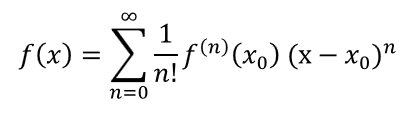

W praktyce inżynierskiej często wystarczające okazuje się uwzględnienie dwóch (lub ew. trzech) pierwszych wyrazów tego szeregu:

 lub 

Obrazuje to poniższy przykład, który pozwala wyznaczyć dokładność takiego przybliżenia w zależności od odległości punktu *x* od punktu *x0* (odległość tę oznaczono zmienną *h*). Wybierz funkcję, punkt, który będzie przyjmowany za znany oraz liczbę elementów szeregu, które zostaną uwzględnione w obliczeniach:

clear all;
close all;
%zwybór funkcji, której będzie obliczana całka
syms f(x)
f(x)=sin(x)

$$f(x) = \sin\left(x\right)$$

%Rozwiń wokół domyślnego punktu:
deafX0=true

deafX0 = logical
   1


%clear f
%f=@(x) exp(1).^(25*x)

if deafX0==true
    x0=0.01
else
    x0=input("Podaj x0, wokół którego funkcja zostanie rozwinięta w szereg:")
end

x0 = 0.0100


%Wybierz liczbę elementów szeregu dla przybliżenia
N=2

N = 2


 

disp('Wartosc funkcji f(x0) = ')

Wartosc funkcji f(x0) = 


double(f(x0))

ans = 0.0100

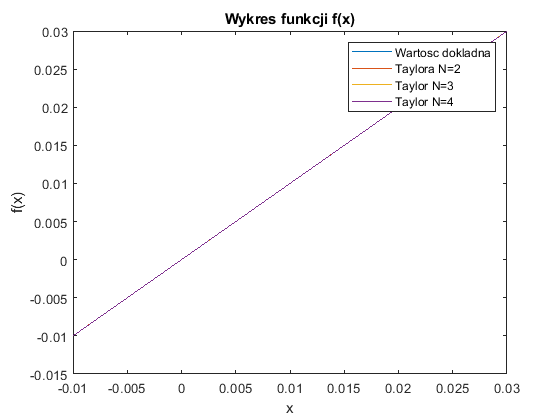

%liczba punktów na wykresie i zakres h
LP=100000;
zakresH=0.02;

%WYZNACZANIE POCHODNYCH%%%%%%%%%%%
if strcmp(string(char(f(x))),"sin(x)")
        fprim=@(x) cos(x);
        fbis=@(x) -sin(x);
        ftert=@(x) -cos(x);
end
if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        fprim=@(x) 3*x^2-4*x-5;
        fbis=@(x) 6*x-4;
        ftert=@(x) 6;
end
if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        fprim=@(x) 6*x^5+12*x^3-2;
        fbis=@(x) 30*x^4+36*x^2;
        ftert=@(x) 120*x^3+72*x;
end
if strcmp(string(char(f(x))),"exp(x)")
        fprim=@(x) exp(x);
        fbis=@(x) exp(x);
        ftert=@(x) exp(x);
end
%fprim=@(x) 25*exp(1).^(25*x)
%fbis=@(x) 625*exp(1).^(25*x)
%ftert=@(x) 25^3*exp(1).^(25*x)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

h=linspace(-zakresH,zakresH,LP);
fx_dokl=double(f(x0+h));
%if N==2
    fx_T2=double(f(x0))+h.*fprim(x0);
%elseif N==3
    fx_T3=double(f(x0))+h.*fprim(x0)+1/2.*h.^2*fbis(x0);
%elseif N==4
    fx_T4=double(f(x0))+h.*fprim(x0)+1/2.*h.^2*fbis(x0)+1/6.*h.^3*ftert(x0);
%end

figure()
plot(x0+h, fx_dokl,x0+h,fx_T2,x0+h, fx_T3,x0+h, fx_T4)
title 'Wykres funkcji f(x)'
xlabel 'x'
ylabel 'f(x)'
legend('Wartosc dokladna', 'Taylora N=2', 'Taylor N=3', 'Taylor N=4')

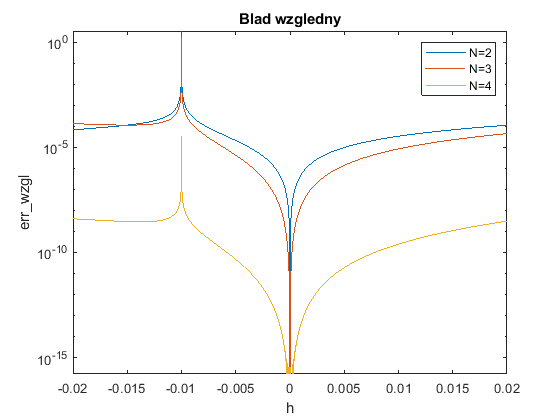



err_bw2=abs(fx_dokl-fx_T2);
err_bw3=abs(fx_dokl-fx_T3);
err_bw4=abs(fx_dokl-fx_T4);

err_wzgl2=err_bw2./abs(fx_dokl);
err_wzgl3=err_bw3./abs(fx_dokl);
err_wzgl4=err_bw4./abs(fx_dokl);

%figure()
%semilogy(h,err_bw)
%title 'Blad bezwzgledny'
%xlabel 'h'
%ylabel 'err\_bw'

figure()
semilogy(h,err_wzgl2, h,err_wzgl3, h,err_wzgl4, '-')
title 'Blad wzgledny'
xlabel 'h'
ylabel 'err\_wzgl'
legend('N=2', 'N=3', 'N=4')